This file contains tests for the various HyPro set representations. 

inter = [1 2; 3 4; 5 6; 7 8; 9 10];
points = [0 0; 2 2];
insert_inter = [12 41];
mat = [1 0 0; 0 1 0; 0 0 1];
vec = [1; 2; 3];
single_inter = [2 4];

**Tests for HyPro Boxes**

First create some boxes. To call a constructor one needs to call

**HyProObject**(t*ype, constructor, args*)

where '*type*' is the type of the set representation (here 'Box'), *'constructor*' is the name of constructor you want use to create a new HyProObjects (the constructor names vary for the various set representations), and '*args*' which are arguments needed to construct a new HyProObject.

First, create an empty box. The corresponding constructor is *'new_empty*'

disp('Construct empty box');

Construct empty box


box_0 = HyProObject('Box','new_empty');


box_0 is now a empty HyPro box. To see this, one can call the function* intervals()* on this box and see that the list of intervals is empty.

intervals_box_0 = box_0.intervals();
disp('Box 0 intervals:');

Box 0 intervals:


disp(intervals_box_0);


Another possibility is to construct a box using a list of intervals. Here, the corresponding constructor is called *'new_intervals'*.

disp('Construct box from list of intervals');

Construct box from list of intervals


box_1 = HyProObject('Box','new_intervals',[1 3; 2 4]);
intervals_box_1 = box_1.intervals();
disp('Box 1 intervals:');

Box 1 intervals:


disp(intervals_box_1);

     1     3
     2     4



To plot the boxes one has to call the *plot* function. One has to enter the dimensions that one wants to plot:

disp('Plot box_1:');

Plot box_1:


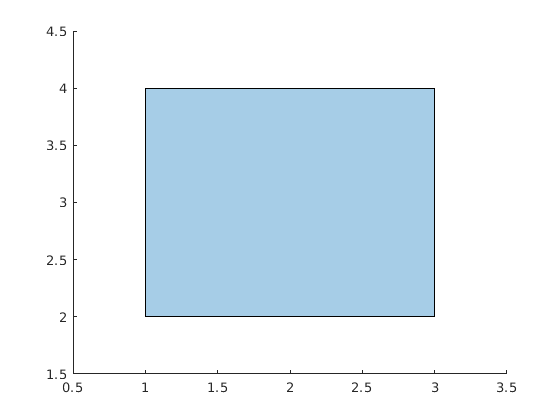

box_1.plot([1 2]);

It is also possible to construct a HyPro box using two points - the max. and min. point limiting the box.

disp('Construct box from a pair of points');

Construct box from a pair of points


box_2 = HyProObject('Box','new_points',points);
box_2_inter = box_2.intervals();
disp('Box 2 intervals:');

Box 2 intervals:


disp(box_2_inter);

     0     0
     2     2



To make a copy of an already existing box one has to use the *'copy'* constructor. Here, we make a copy of box_3.

disp('Copy a box');

Copy a box


box_3 = HyProObject('Box','new_intervals',inter);
box_4 = HyProObject('Box', 'copy', box_3);
box_4_inter = box_4.intervals();
disp('Box 4 intervals:');

Box 4 intervals:


disp(box_4_inter);

     1     2
     3     4
     5     6
     7     8
     9    10



Here for example we can plot the 3rd and 4th dimension of the box as follows:

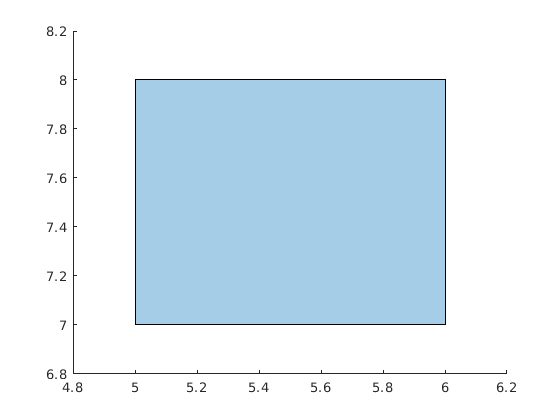

disp('3rd and 4th dimension of box 4:');
box_4.plot([3 4]);

Another possibility is to use matrix and a vector to construct a new box.

disp('Construct box from matrix and vector');

Construct box from matrix and vector


box_5 = HyProObject('Box','new_matrix',mat,vec);
box_5_inter = box_5.intervals();
disp('Box 5 intervals:');

Box 5 intervals:


disp(box_5_inter);

     1     1
     2     2
     3     3



Last possibility is to construct a box by using only one single interval.

disp('Construct box from single interval');

Construct box from single interval


box_6 = HyProObject('Box','new_interval',single_inter);
box_6_inter = box_6.intervals();
disp('Box 6 interval:');

Box 6 interval:


disp(box_6_inter);

     2     4




%**************************Getters&Setters*********************************

disp('Insert');

Insert


box_7 = HyProObject('Box', 'new_intervals',inter);
old_intervals = box_7.intervals();
disp('Old intervals:');

Old intervals:


disp(old_intervals);

     1     2
     3     4
     5     6
     7     8
     9    10



box_7.insert(insert_inter);
new_intervals = box_7.intervals();
disp('New intervals:');

New intervals:


disp(new_intervals);

     1     2
     3     4
     5     6
     7     8
     9    10
    12    41




disp('Empty');

Empty


box_8 = HyProObject('Box','new_intervals',inter);
old_intervals = box_8.intervals();
disp('Old intervals:');

Old intervals:


disp(old_intervals);

     1     2
     3     4
     5     6
     7     8
     9    10



box_8_1 = box_8.empty(2);
new_intervals = box_8_1.intervals();
disp('New intervals:');

New intervals:


disp(new_intervals);

     0     0
     0     0




disp('Limits');

Limits


box_9 = HyProObject('Box','new_intervals',inter);
limits = box_9.limits();
disp('Limits of box 9:');

Limits of box 9:


disp(limits);

     1     3
     2     4




disp('Constraints');

Constraints


%box_10

disp('Interval');

Interval


box_11 = HyProObject('Box','new_intervals',inter);
inter_11 = box_11.interval(2);
disp('Box 11 interval at position 2:');

Box 11 interval at position 2:


disp(inter_11);

     5     6




disp('At');

At


box_12 = HyProObject('Box', 'new_intervals',inter);
inter_12 = box_12.at(3);
disp('Box 12 interval at position 3:');

Box 12 interval at position 3:


disp(inter_12);

     7     8




disp('Is Empty');

Is Empty


box_13 = HyProObject('Box', 'new_intervals',inter);
a = box_13.isempty();
disp('Is box 13 empty? :');

Is box 13 empty? :


disp(a);

   0



box_14 = HyProObject('Box', 'new_empty');
b = box_14.isempty();
disp('Is box 14 empty? :');

Is box 14 empty? :


disp(b);

   1




disp('Is Symmetric');

Is Symmetric


box_15 = HyProObject('Box','new_intervals', [1 2; 1 2]);
a = box_15.isSymmetric();
disp('Is box 15 symmetric? :');

Is box 15 symmetric? :


disp(a);

   0



box_16 = HyProObject('Box', 'new_intervals', [-1 1; -1 1]);
b = box_16.isSymmetric();
disp('Is box 16 symmetric? :');

Is box 16 symmetric? :


disp(b);

   1




disp('Get Max');

Get Max


box_17 = HyProObject('Box','new_intervals', [1 2; 1 2]);
m = box_17.max();
disp('Box 17 max:');

Box 17 max:


disp(m);

     2     0




disp('Get Min');

Get Min


box_18 = HyProObject('Box','new_intervals', [1 2; 1 2]);
m = box_18.min();
disp('Box 18 min:');

Box 18 min:


disp(m);

     1     0




disp('Get Supremum');

Get Supremum


box_19 = HyProObject('Box','new_intervals', [1 2; 1 2]);
m = box_19.supremum();
disp('Box 19 supremum:');

Box 19 supremum:


disp(m);

     2




disp('Get Vertices');

Get Vertices


box_20 = HyProObject('Box','new_intervals', [0 1; 0 1; 0 1]);
m = box_20.vertices();
disp('Box 20 vertices:');

Box 20 vertices:


disp(m);

     0     0     0
     1     0     0
     0     1     0
     1     1     0
     0     0     1
     1     0     1
     0     1     1
     1     1     1




% disp('Evaluate');
% box_21 = HyProObject('Box','new_intervals', [1 5; 2 7]);
% vec = [1 0];
% dir = 0;
% eval = box_21.evaluate(vec, dir);
% One has to delete eval again! - Destructor needed
% 
% disp('MutliEvaluate');
% %box_22

disp('==');

==


box_23 = HyProObject('Box', 'new_intervals', [1 2; 1 2]);
box_24 = HyProObject('Box','new_intervals', [1 2; 1 2]);
disp('Are box 23 and box 24 equal? :');

Are box 23 and box 24 equal? :


a = (box_23 == box_24);
disp(a);

   1



box_25 = HyProObject('Box','new_intervals', [1 2; 2 5; 1 2]);
disp('Are box 23 and box 25 equal? :');

Are box 23 and box 25 equal? :


a = box_23.eq(box_25);
disp(a);

   0




disp('!=');

!=


box_26 = HyProObject('Box','new_intervals', [1 2; 1 2]);
box_27 = HyProObject('Box','new_intervals', [1 2; 1 2]);
disp('Are box 26 and box 27 unequal? :');

Are box 26 and box 27 unequal? :


a = (box_26 ~= box_27);
disp(a);

   0



box_28 = HyProObject('Box','new_intervals', [1 2; 2 5; 2 3]);
disp('Are box 26 and box 28 unequal? :');

Are box 26 and box 28 unequal? :


a = (box_26 ~= box_28);
disp(a);

   1




disp('Dimension');

Dimension


box_29 = HyProObject('Box','new_intervals', [1 2; 1 2]);
dim = box_29.dimension();
disp('Box 29 dimension: ');

Box 29 dimension: 


disp(dim);

     2




disp('Make Symmetric');

Make Symmetric


box_30 = HyProObject('Box','new_intervals',[1 2; 1 4]);
old_intervals = box_30.intervals();
disp('Old intervals:');

Old intervals:


disp(old_intervals);

     1     2
     1     4



box_30.makeSymmetric();
new_intervals = box_30.intervals();
disp('New intervals:');

New intervals:


disp(new_intervals);

     1     2
     1     4




% disp('Constraints');
% box_31 = HyProObject('Box','new_intervals', [3 5; 2 4]);
% [normal_vecs, offsets] = box_31.constraints();
% disp(normal_vecs);
% disp(offsets);

disp('Satisfies Halfspace');

Satisfies Halfspace


box_32 = HyProObject('Box','new_intervals', [3 5; 2 4]);
hs_normal = [1 0];
hs_offset = 2;
[containment, box] = box_32.satisfiesHalfspace(hs_normal, hs_offset);
disp('containment:');

containment:


disp(containment);

NO



disp('Satisfies Halfspaces');

Satisfies Halfspaces


box_33 = HyProObject('Box', 'new_intervals', [3 5; 2 4]);
mat = [1 0; 0 1];
vec = [2 3];
[containment, box] = box_33.satisfiesHalfspaces(mat, vec);
disp('containment:');

containment:


disp(containment);

NO



disp('Project');

Project


box_34 = HyProObject('Box','new_intervals', [3 5; 2 4; 1 2]);
dims = 2;
box = box_34.project(dims);
inter = box.intervals();
disp('Intervals of the new box:');

Intervals of the new box:


disp(inter);

     1     2




disp('Linear Transformation');

Linear Transformation


box_35 = HyProObject('Box','new_intervals', [3 5; 2 4]);
mat = [2 0; 0 4];
box = box_35.linearTransformation(mat);
inter = box.intervals();
disp('Intervals of the transformed box:');

Intervals of the transformed box:


disp(inter);

     6    10
     8    16




disp('Affine Transformation');

Affine Transformation


box_36 = HyProObject('Box','new_intervals', [3 5; 2 4]);
mat = [2 0; 0 4];
vec = [2 1];
box = box_36.affineTransformation(mat, vec);
inter = box.intervals();
disp('Intervals of the transformed box:');

Intervals of the transformed box:


disp(inter);

     8    12




disp('Minkowski Sum');

Minkowski Sum


box_37 = HyProObject('Box','new_intervals', [1 3; 1 3]);
box_38 = HyProObject('Box', 'new_intervals', [4 6; 3 5]);
mSum = box_3 + box_38;
inter = mSum.intervals();
disp('Intervals of the sum:');

Intervals of the sum:


disp(inter);

    5.0000    8.0000
    6.0000    9.0000
    5.0000    6.0000
         0         0
         0         0




disp('Minkowski Decomposition');

Minkowski Decomposition


box_39 = HyProObject('Box', 'new_intervals', [1 3; 1 3]);
box_40 = HyProObject('Box', 'new_intervals', [4 6; 3 5]);
mDec = box_39.minkowskiDecomposition(box_40);
inter = mDec.intervals();
disp('Intervals:');

Intervals:


disp(inter);

    -3    -3
    -2    -2




disp('Intersect');

Intersect


box_41 = HyProObject('Box', 'new_intervals', [1 3; 1 3]);
box_42 = HyProObject('Box', 'new_intervals', [4 6; 3 5]);
intersected = box_41.intersect(box_42);
inter = intersected.intervals();
disp('Intervals:');

Intervals:


disp(inter);

     0     0
     3     3




disp('Intersect Halfspace');

Intersect Halfspace


box_43 = HyProObject('Box','new_intervals', [1 3; 1 3]);
nor = [1 0];
off = 2;
intersected = box_43.intersectHalfspace(nor,off);
inter = intersected.intervals();
disp('Intervals:');

Intervals:


disp(inter);

     1     2
     1     3




disp('Intersect Halfspaces');

Intersect Halfspaces


box_44 = HyProObject('Box','new_intervals', [1 3; 1 3]);
mat = [1 0; 0 1];
vec = [2 3];
intersected = box_44.intersectHalfspace(mat,vec);
inter = intersected.intervals();
disp('Intervals:');

Intervals:


disp(inter);

     1     2
     1     3




disp('Contains Point');

Contains Point


box_45 = HyProObject('Box','new_intervals', [1 3; 2 5]);
point = [2; 3];
contains = box_45.contains(point);
disp('Box 45 contains point (2, 3):');

Box 45 contains point (2, 3):


disp(contains);

   1




disp('Contains Box');

Contains Box


box_46 = HyProObject('Box', 'new_intervals', [1 5; 1 7]);
box_47 = HyProObject('Box', 'new_intervals', [2 4; 2 3]);
contains = box_46.contains(box_47);
disp('Box 46 contains box 47:');

Box 46 contains box 47:


disp(contains);

   1




disp('Unite Box');

Unite Box


box_48 = HyProObject('Box', 'new_intervals', [1 5; 1 7]);
box_49 = HyProObject('Box', 'new_intervals', [2 7; -1 9]);
uni = box_48.unite(box_49);
disp('Unite boxes 48 and 49:');

Unite boxes 48 and 49:


inter = uni.intervals();
disp('Intervals:');

Intervals:


disp(inter);

     2     7
    -1     9




% disp('Unite Boxes');
% box_50 = HyProObject('Box','new_intervals', [1 5; 1 7]);
% box_51 = HyProObject('Box','new_intervals', [2 7; -1 9]);
% box_52 = HyProObject('Box','new_intervals', [0 1; 9 10]);
% boxes = {box_51, box_52};
% box_50.unite(boxes);
% out = HyProObject('unite_boxes', box_50, boxes);
% disp('Unite boxes 50, 51, and 52:');
% inter = HyProObject('intervals', uni);
% disp('Intervals:');
% disp(inter);
% HyProObject('delete', box_50);
% HyProObject('delete', box_51);
% HyProObject('delete', box_52);
% HyProObject('delete', uni);

disp('* (Scale)');

* (Scale)


box_53 = HyProObject('Box', 'new_intervals', [1 5; 1 7]);
box_54 = box_53 * 3;
inter = box_54.intervals();
disp('Intervals:');

Intervals:


disp(inter);

     3    15
     3    21




disp('<<');

<<


box_54 = HyProObject('Box', 'new_intervals', [1 5; 1 7]);
box_54.ostream();

Min: [1.000000 1.000000 ] Max: [5.000000 7.000000 ]


m = box_54.matrix();
disp('Matrix of box_54');

Matrix of box_54


disp(m);

     1     0
    -1     0
     0     1
     0    -1



v = box_54.vector();
disp('Vector of box_54');

Vector of box_54


disp(v);

     5
    -1
     7
    -1




disp('reduceNumberRepresentation');

reduceNumberRepresentation


box_55 = HyProObject('Box', 'new_intervals', [1 5; 1 7; 1 2; 2 3]);
box_56 = box_55.reduceNumberRepresentation();
inter = box_56.intervals();
disp('Intervals:');

Intervals:


disp(inter);

     1     5
     1     7
     1     2
     2     3




%**************************************************************************
% Tests for HyPro Ellipsoids
%**************************************************************************

eli_1 = HyProObject('Ellipsoid', 'ellipsoid', 2, 2);
eli_2 = HyProObject('Ellipsoid', 'copy', eli_1);
eli_3 = HyProObject('Ellipsoid', 'ellipsoid_mat', [1 2 3; 4 5 6; 7 8 9]);

disp("Is ellipse 1 empty?: ");

Is ellipse 1 empty?: 


disp(eli_1.isempty());

   0




disp("Ellipse 3 matrix:");

Ellipse 3 matrix:


disp(eli_3.matrix());

     1     2     3
     4     5     6
     7     8     9




disp("Ellipse 3 dimension:");

Ellipse 3 dimension:


disp(eli_3.dimension());

     3




disp("Are ellipsoids 1 and 3 equal?");

Are ellipsoids 1 and 3 equal?


disp(eli_3 == eli_1);

   0




disp("Are ellipsoids 2 and 1 equal?");

Are ellipsoids 2 and 1 equal?


disp(eli_1 == eli_2);

   1




disp("Are ellipsoids 1 and 3 unequal?");

Are ellipsoids 1 and 3 unequal?


disp(eli_3 ~= eli_1);

   1




disp("Are ellipsoids 2 and 1 unequal?");

Are ellipsoids 2 and 1 unequal?


disp(eli_1 ~= eli_2);

   0




disp("Ellipse 3:");

Ellipse 3:


eli_3.ostream();

Matrix: [1.000000 2.000000 3.000000 
4.000000 5.000000 6.000000 
7.000000 8.000000 9.000000 
]



disp('Linear Transformation');

Linear Transformation


mat = [2 0; 3 4];
eli_4 = eli_3.linearTransformation(mat);
mat = eli_4.matrix();
disp('Matrix of the transformed ellipsoid:');

Matrix of the transformed ellipsoid:


disp(mat);

     4    22
    38   161




disp('Affine Transformation');

Affine Transformation


mat = [2 2; 0 4];
vec = [2 1];
eli_5 = eli_3.affineTransformation(mat, vec);
mat = eli_5.matrix();
disp('Matrix of the transformed ellipsoid:');

Matrix of the transformed ellipsoid:


disp(mat);

    48    56
    72    80




disp('Minkowski sum');

Minkowski sum


eli_6 = eli_4 + eli_5;
mat = eli_6.matrix();
disp('Minkowski sum of eli_4 and eli_5:');

Minkowski sum of eli_4 and eli_5:


disp(mat);

   79.7128  170.3760
  170.3760  821.8144




disp('ApproxEllipsoidMatrix');

ApproxEllipsoidMatrix


mat = eli_6.approxEllipsoidMatrix([4 2; 0 8]);
disp('Matrix app. of ellipsoid 6:');

Matrix app. of ellipsoid 6:


disp(mat);

     4     2
     2     8




disp('Passed');

Passed
